## ECE572 - HW3

### Reza Jahani - Rjahani@ncsu.edu

f = @(x1,x2) (x1 - x2).^4 + 12*x1.*x2 - x1 + x2 - 3;
    f_val = @(x) f(x(1),x(2));

Problem 2 - Rank One

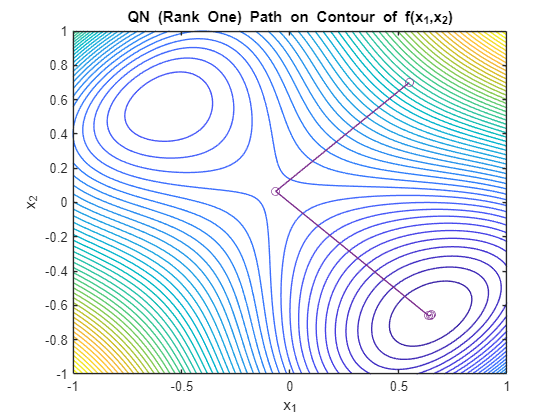

mode = 1;
%%% x0_1
x0 = [0.55;0.7];

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 50); hold on;
xlabel('x_1'); ylabel('x_2');
title('QN (Rank One) Path on Contour of f(x_1,x_2)');
x_star = Quassi_Newton(x0,mode);
hold off;

disp("x_star =")

x_star =


disp(x_star)

    0.6504
   -0.6504



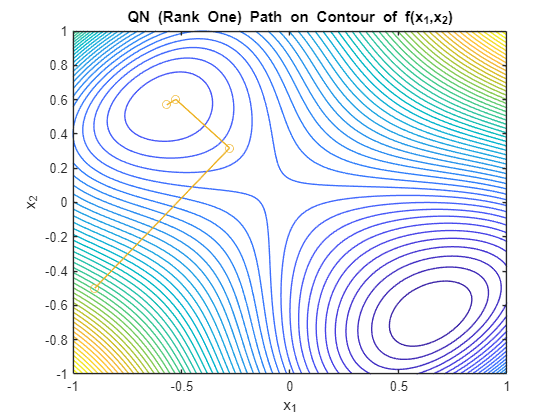

%%% x0_2
mode = 1;
x0 = [-0.9;-0.5];

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 50); hold on;
xlabel('x_1'); ylabel('x_2');
title('QN (Rank One) Path on Contour of f(x_1,x_2)');
x_star = Quassi_Newton(x0,mode);
hold off;

disp("x_star =")

x_star =


disp(x_star)

   -0.5679
    0.5691



Problem 3 - DFP

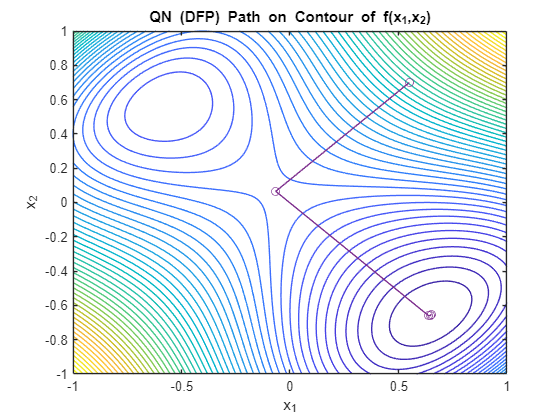

mode = 2;
%%% x0_1
x0 = [0.55;0.7];

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 50); hold on;
xlabel('x_1'); ylabel('x_2');
title('QN (DFP) Path on Contour of f(x_1,x_2)');
x_star = Quassi_Newton(x0,mode);
hold off;

disp("x_star =")

x_star =


disp(x_star)

    0.6504
   -0.6504



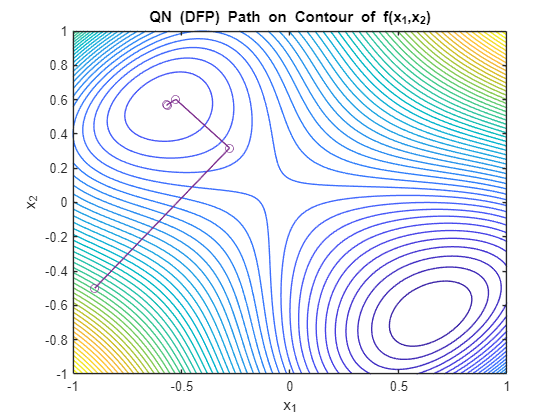

%%% x0_2
mode = 2;
x0 = [-0.9;-0.5];

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 50); hold on;
xlabel('x_1'); ylabel('x_2');
title('QN (DFP) Path on Contour of f(x_1,x_2)');
x_star = Quassi_Newton(x0,mode);
hold off;

disp("x_star =")

x_star =


disp(x_star)

   -0.5655
    0.5655



Problem 4 - BFGS

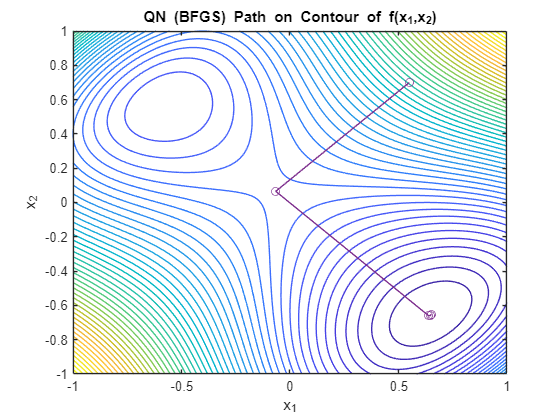

%%% x0_1
mode = 3;
x0 = [0.55;0.7];

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 50); hold on;
xlabel('x_1'); ylabel('x_2');
title('QN (BFGS) Path on Contour of f(x_1,x_2)');
x_star = Quassi_Newton(x0,mode);
hold off;

disp("x_star =")

x_star =


disp(x_star)

    0.6504
   -0.6504



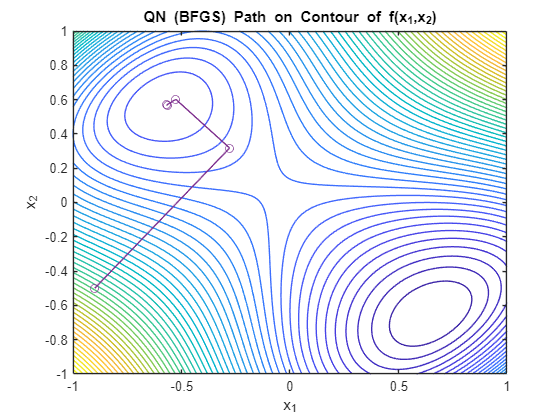

%%% x0_2
mode = 2;
x0 = [-0.9;-0.5];

[X1, X2] = meshgrid(-1:0.01:1, -1:0.01:1);
F = f(X1, X2);
contour(X1, X2, F, 50); hold on;
xlabel('x_1'); ylabel('x_2');
title('QN (BFGS) Path on Contour of f(x_1,x_2)');
x_star = Quassi_Newton(x0,mode);
hold off;

disp("x_star =")

x_star =


disp(x_star)

   -0.5655
    0.5655



**Functions**

function delta_H = QN_dH(H,dx,dg,mode)

    if mode == 1
       delta_H = ((dx - H*dg)*(dx-H*dg)')/((dg')*(dx-H*dg)); 
    end
    if mode == 2
       delta_H = (dx*dx')/(dx'*dg) - ((H*dg)*(H*dg)')/(dg'*H*dg);
    end
    if mode == 3
       term1 = (1 + (dg' * H * dg) / (dg' * dx)) * (dx * dx') / (dg' * dx);
        term2 = (H * dg * dx' + (H * dg * dx')') / (dg' * dx);
        delta_H = term1 - term2; 
    end

end

function x = Quassi_Newton(x0,mode)
    
    f = @(x1,x2) (x1 - x2).^4 + 12*x1.*x2 - x1 + x2 - 3;
    f_val = @(x) f(x(1),x(2));
    grad_f = @(x) [4*(x(1)-x(2))^3 + 12*x(2) - 1;
                  -4*(x(1)-x(2))^3 + 12*x(1) + 1];

    err = 1e-5;

    x = x0;
    H = eye(length(x0));
    N = 100;
    
    path = x0;

    for k=1:N
        g_k = grad_f(x);
        d_k = - H * g_k;
        
        alpha = line_search(x,d_k);
    
        x_old = x;
        x = x + alpha*d_k;
        g_new = grad_f(x);
    
        d_x = x - x_old;
        d_g = g_new - g_k;
    
        delta_H = QN_dH(H,d_x,d_g,mode);
        H = H + delta_H;

        
        if norm(x-x_old) <= err
            break;
        end 

        path = [path, x];
        plot(path(1,:), path(2,:), '-o');

    end
end

function alpha = line_search(x, d_k)

    f = @(x1,x2) (x1 - x2).^4 + 12*x1.*x2 - x1 + x2 - 3;
    f_val = @(x) f(x(1),x(2));
    phi = @(alpha) f_val(x + alpha*d_k);  
    
    a = 0;
    b = 1;
    phi_a = phi(a);
    phi_b = phi(b);

    while phi_b < phi_a
        b = 2*b;
        phi_b = phi(b);
        if b > 10
            break;
        end
    end

    rho = 0.618;
    s = b - rho*(b - a);
    t = a + rho*(b - a);
    f1 = phi(s);
    f2 = phi(t);

    eps = 1e-4;
    N = 1000;
    for n = 1:N
        if f1 < f2
            b = t;
            t = s;
            s = b - rho*(b - a);
            f2 = f1;
            f1 = phi(s);
        else
            a = s;
            s = t;
            t = a + rho*(b - a);
            f1 = f2;
            f2 = phi(t);
        end

        if abs(b - a) < eps
            break;
        end
    end

    if f1 < f2
        alpha = s;
    else
        alpha = t;
    end
end
